# M-SPARC and KSSOLV Simulations

In this live script we showcase 2 DFT community toolboxes, M-SPARC and KSSOLV. These are Kohn-Sham DFT solvers in real-space and momemtum-space using plane wave basis, respectively. Both toolboxes are 3-Dimensional pseudopotential implementation of Kohn-Sham theory and can work with norm-conserving pseudopotentials in psp8 format. Here we use the default pseudopotential files porvided within the toolboxes. We need 2 toolboxes to be downloaded and installed, with their paths added properly. To download the toolboxes, use the following links: [https://github.com/SPARC-X/M-SPARC](https://github.com/SPARC-X/M-SPARC) for M-SPARC and [https://bitbucket.org/berkeleylab/kssolv2.0/src/release/](https://bitbucket.org/berkeleylab/kssolv2.0/src/release/) for KSSOLV. After downloading the toolboxes, put their paths below. Don't remove the M-SPARC/ and KSSOLV/ folder in the directory. Afterwards, you can start the simulations. 

MSPARC_root = 'C:\Users\tvekua\OneDrive - MathWorks\Desktop\DFTMaterial\M-SPARC';
KSSOLV_root = 'C:\Users\tvekua\OneDrive - MathWorks\Desktop\DFTMaterial\kssolv2.0';

if ~exist('M-SPARC', 'dir') || ~exist('KSSOLV', 'dir') 
   error('Do not remove M-SPARC/ and KSSOLV/ folder!');
end

## Monoatomic Molecules (Atoms)

We start with simulating a monoatomic molecule, an atom. First we select atom symbol and specify linear size (length) of the finite simulation cube in units of Bohr radius. The atom will be placed at the center of the cube. The cube should be sufficiently large to achieve desired accuracy.  

atom = 'He'; % atom symbol
L1 = 20;   % linear size of unit cell in Bohr radius

For M-SPARC, here we select mesh size (step size) in real space in units of Bohr radius. In practice, we need to do a mesh convergence test to get an accurate result. 

h1 = 0.2; % in Bohr
% path and check
addpath(MSPARC_root);
addpath(fullfile(MSPARC_root,"src"));
addpath("M-SPARC\");
% Real space toolbox M-SPARC
msparc_monoatomMol(atom,L1,h1,MSPARC_root);
S1 = msparc("M-SPARC/monoatom");

 Reading .inpt file ...


<INPT>
# $ cat M-SPARC/monoatom.inpt
LATVEC_SCALE: 20.000000 20.000000 20.000000
MESH_SPACING: 0.200000
BC: D D D
EXCHANGE_CORRELATION: GGA_PBE
<\INPT>

 Reading .ion file ...
 Number of atom types : 1
 Total number of atoms: 1
 Default atomic mass for He is 4.002602
 pseudo_dir # 1 = 02_He_2_1.1_1.2_pbe_v1.0.psp8

 COORD:
    10    10    10

atom type 1, l = 0, r_core read 1.25127, change to rmax where |UdV| < 1E-8, 1.27000.
atom type 1, l = 1, r_core read 1.13028, change to rmax where |UdV| < 1E-8, 1.15000.
 reduced kpoint grid before symmetry:
     0     0     0

 reduced kpoint grid after symmetry:
     0     0     0

 nspin = 1, nspinor = 1, nspden = 1
## Chebyshev polynomial degree not provided, finding npl ...
## Based on the mesh size, npl is set to: 35
## Number of states not provided, finding Nev ...
## Based on the number of electrons, Nev is set to: 6
## Based on the desired accuracy, SCF_tol is set to: 2.159e-04
## Poisson tolerance not provided, 

rmpath(MSPARC_root);
rmpath(fullfile(MSPARC_root,"src"));
rmpath("M-SPARC\");

Here we choose Kinetic energy cutoff in momentum space $E_{cut}$ in units of Hartree for KSSOLV. Usually, we need to perform convergence test in $E_{cut}$ as well.

Ecut1 = 20; % in Ha

% path and check
addpath(KSSOLV_root);
addpath("KSSOLV\");
KSSOLV_startup;
[K_mol1,K_Ham1,K_wf1,K_info1] = kssolv_monoatomMol(atom,L1,Ecut1);

The pseudopotential for He is loaded from C:\Users\tvekua\OneDrive - MathWorks\Desktop\DFTMaterial\KSSOLV\/ppdata/default/He_ONCV_PBE-1.0.upf
The pseudopotential for He is loaded from C:\Users\tvekua\OneDrive - MathWorks\Desktop\DFTMaterial\KSSOLV\/ppdata/default/He_ONCV_PBE-1.0.upf
Regular SCF for Pure DFT
Beging SCF calculation for He...
SCF iter   1:
eigtol =   1.000e-02
Rel Vtot Err    =            5.856e-02
Total Energy    = -2.7904730741642e+00
SCF iter   2:
eigtol =   1.000e-02
Rel Vtot Err    =            1.173e-02
Total Energy    = -2.7904731226360e+00
SCF iter   3:
eigtol =   5.867e-03
Rel Vtot Err    =            1.389e-04
Total Energy    = -2.7904731236473e+00
SCF iter   4:
eigtol =   6.943e-05
Rel Vtot Err    =            4.708e-05
Total Energy    = -2.7904731236658e+00
SCF iter   5:
eigtol =   2.354e-05
Rel Vtot Err    =            7.349e-07
Total Energy    = -2.7904731236661e+00
SCF iter   6:
eigtol =   3.675e-07
Rel Vtot Err    =            2.327e-08
Total Energy    = -

rmpath(KSSOLV_root);
rmpath("KSSOLV\");
fprintf("Total energy of single atom %s molecule from M-SPARC is %.6f Ha\n", atom, S1.Etotal);

Total energy of single atom He molecule from M-SPARC is -2.853185 Ha


fprintf("Total energy of single atom %s molecule from KSSOLV is %.6f Ha\n", atom, K_info1.Etot);

Total energy of single atom He molecule from KSSOLV is -2.790473 Ha


Next, we visualize the radial electron density obtained from 2 toolboxes below. 

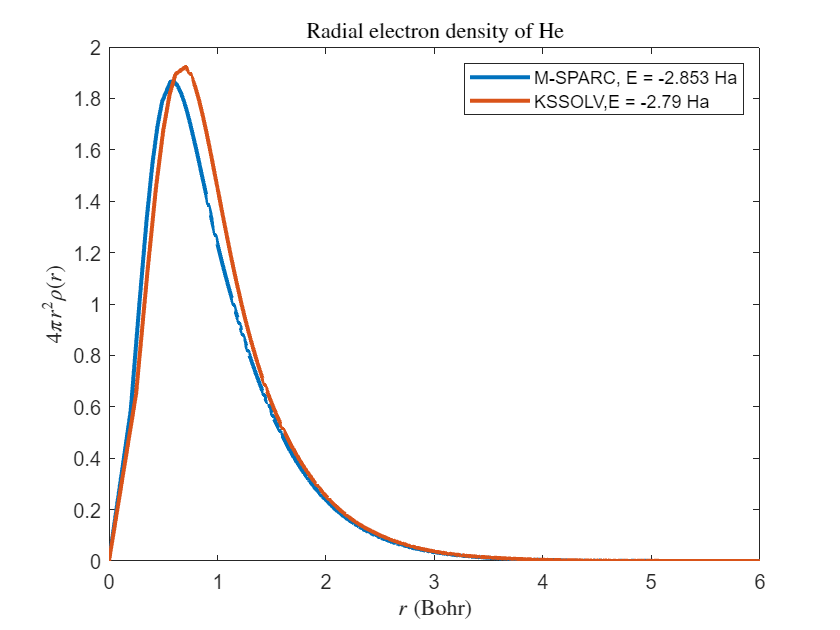

% M-SPARC
rhom = S1.rho(:,1);
x = linspace(-L1/2,L1/2,S1.Nx);
y = linspace(-L1/2,L1/2,S1.Ny);
z = linspace(-L1/2,L1/2,S1.Nz);
[X,Y,Z] = ndgrid(x,y,z);
[~,~,Rm] = cart2sph(X,Y,Z);
Rm = Rm(:);
rrhom = 4*pi*Rm.^2.*rhom;
[Rm,~,indx] = unique(Rm);
rrhom = accumarray(indx, rrhom, [], @mean);

% KSSOLV
rhok = reshape(fftshift(K_Ham1.rho),[],1);
x = linspace(-L1/2,L1/2,K_Ham1.n1);
y = linspace(-L1/2,L1/2,K_Ham1.n2);
z = linspace(-L1/2,L1/2,K_Ham1.n3);
[X,Y,Z] = ndgrid(x,y,z);
[~,~,Rk] = cart2sph(X,Y,Z);
Rk = Rk(:);
rrhok = 4*pi*Rk.^2.*rhok;
[Rk,~,indx] = unique(Rk);
rrhok = accumarray(indx, rrhok, [], @mean);

figure
plot(Rm,rrhom,Rk,rrhok,'LineWidth',2)
legend("M-SPARC, E = " + num2str(S1.Etotal,4) + " Ha","KSSOLV,E = " + num2str(K_info1.Etot,4) + " Ha")
xlabel("$r$ (Bohr)",'Interpreter','latex')
ylabel("$4\pi r^2 \rho(r)$",'Interpreter','latex') 
title(['Radial electron density of ', atom],'Interpreter','latex')
xlim([0 6])

## Diatomic Molecules

Next, we present the calculation on diatomic molecules using 2 toolboxes. We can select 2 atoms from the dropbox below. Again we need to define the linear size of the simulation cube and the bond length $d$ in Bohr.  

atom1 = 'Na'; % atom1 symbol
atom2 = 'Cl'; % atom2 symbol
L2 = 12; % in Bohr
d = 2;  % in Bohr

We select the mesh spacing in real-space below. 

h2 = 0.3; % in Bohr

addpath(MSPARC_root);
addpath(fullfile(MSPARC_root,"src"));
addpath("M-SPARC\");
% Real space toolbox M-SPARC
msparc_diatomMol(atom1,atom2,L2,d,h2,MSPARC_root);
S2 = msparc("M-SPARC/diaatom");

 Reading .inpt file ...


<INPT>
# $ cat M-SPARC/diaatom.inpt
LATVEC_SCALE: 12.000000 12.000000 12.000000
MESH_SPACING: 0.300000
BC: D D D
EXCHANGE_CORRELATION: GGA_PBE
<\INPT>

 Reading .ion file ...
 Number of atom types : 2
 Total number of atoms: 2
 Default atomic mass for Na is 22.989769
 Default atomic mass for Cl is 35.451500
 pseudo_dir # 1 = 11_Na_9_1.8_2.2_pbe_v1.0.psp8
 pseudo_dir # 2 = 17_Cl_7_1.9_1.9_pbe_n_v1.0.psp8

 COORD:
     5     6     6
     7     6     6

atom type 1, l = 0, r_core read 1.77096, change to rmax where |UdV| < 1E-8, 1.79000.
atom type 1, l = 1, r_core read 2.20971, change to rmax where |UdV| < 1E-8, 2.22000.
atom type 2, l = 0, r_core read 1.90538, change to rmax where |UdV| < 1E-8, 1.92000.
atom type 2, l = 1, r_core read 1.87149, change to rmax where |UdV| < 1E-8, 1.89000.
atom type 2, l = 2, r_core read 1.90538, change to rmax where |UdV| < 1E-8, 1.92000.
 reduced kpoint grid before symmetry:
     0     0     0

 reduced kpoint grid after symmetry:

rmpath(MSPARC_root);
rmpath(fullfile(MSPARC_root,"src"));
rmpath("M-SPARC\");

Here we choose kinetic energy cutoff in momentum space $E_{cut}$ Ha for KSSOLV again. 

Ecut2 = 20; % in Ha

% path and check
addpath(KSSOLV_root);
addpath("KSSOLV\");
KSSOLV_startup;
[K_mol2,K_Ham2,K_wf2,K_info2] = kssolv_diatomMol(atom1,atom2,L2,d,Ecut2);

The pseudopotential for Na is loaded from C:\Users\tvekua\OneDrive - MathWorks\Desktop\DFTMaterial\KSSOLV\/ppdata/default/Na_ONCV_PBE-1.0.upf
The pseudopotential for Cl is loaded from C:\Users\tvekua\OneDrive - MathWorks\Desktop\DFTMaterial\KSSOLV\/ppdata/default/Cl_ONCV_PBE-1.0.upf
The pseudopotential for Na is loaded from C:\Users\tvekua\OneDrive - MathWorks\Desktop\DFTMaterial\KSSOLV\/ppdata/default/Na_ONCV_PBE-1.0.upf
The pseudopotential for Cl is loaded from C:\Users\tvekua\OneDrive - MathWorks\Desktop\DFTMaterial\KSSOLV\/ppdata/default/Cl_ONCV_PBE-1.0.upf
Regular SCF for Pure DFT
Beging SCF calculation for □Í...
SCF iter   1:
eigtol =   1.000e-02
Rel Vtot Err    =            2.706e-01
Total Energy    = -4.6077794281887e+01
SCF iter   2:
eigtol =   1.000e-02
Rel Vtot Err    =            3.834e-02
Total Energy    = -4.7138689462095e+01
SCF iter   3:
eigtol =   4.793e-03
Rel Vtot Err    =            2.777e-02
Total Energy    = -4.7215731303151e+01
SCF iter   4:
eigtol =   3.471e-03


rmpath(KSSOLV_root);
rmpath("KSSOLV\");
fprintf("Total energy of diatomic (%s-%s) molecule from M-SPARC is %.6f Ha\n", atom1, atom2, S2.Etotal);

Total energy of diatomic (Na-Cl) molecule from M-SPARC is -56.594474 Ha


fprintf("Atomic forces (Ha/Bohr) of diatomic (%s-%s) molecule from M-SPARC are \n %10.6f %10.6f %10.6f\n %10.6f %10.6f %10.6f\n", atom1, atom2, S2.force');

Atomic forces (Ha/Bohr) of diatomic (Na-Cl) molecule from M-SPARC are 
  -2.962471  -0.000027   0.000094
   2.962471   0.000027  -0.000094


fprintf("Total energy of diatomic (%s-%s) molecule from KSSOLV is %.6f Ha\n", atom1, atom2, K_info2.Etot);

Total energy of diatomic (Na-Cl) molecule from KSSOLV is -47.238320 Ha


fprintf("Atomic forces (Ha/Bohr) of diatomic (%s-%s) molecule from KSSOLV are \n %10.6f %10.6f %10.6f\n %10.6f %10.6f %10.6f\n", atom1, atom2, K_mol2.xyzforce');

Atomic forces (Ha/Bohr) of diatomic (Na-Cl) molecule from KSSOLV are 
  10.835215  -0.000000   0.000000
 -10.835240  -0.000000   0.000000


We visualize the contour plot of electron density from both solvers. We can choose the slice that we are interested to visualize below. 

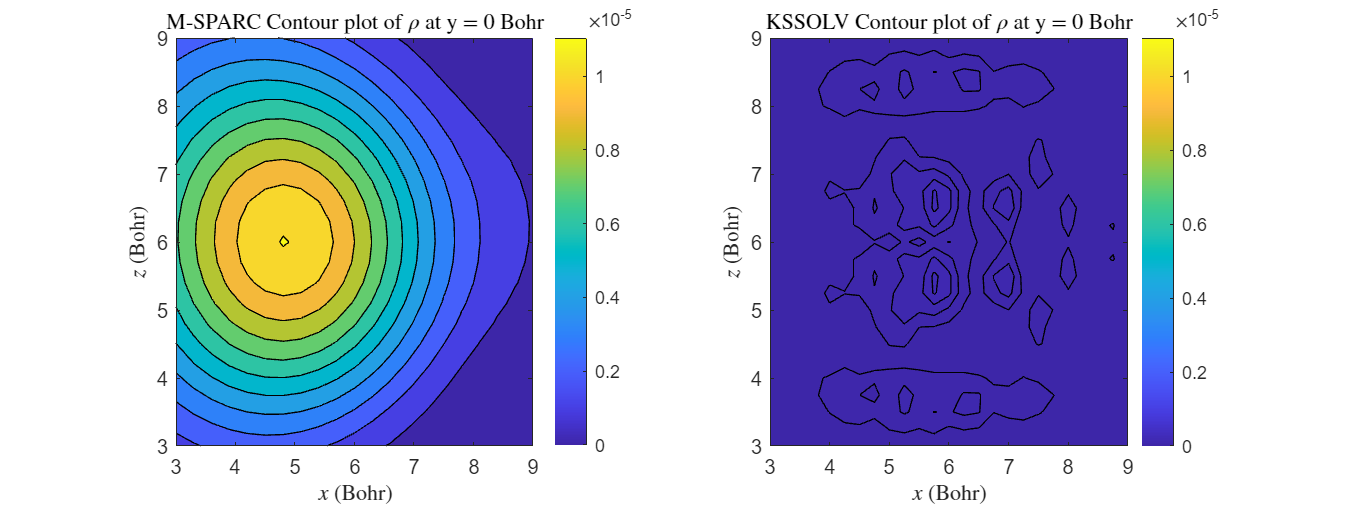

% M-SPARC 
slice_allowed_m = string(linspace(0,S2.L2,S2.Ny));
zslicem = floor(double(slice_allowed_m(1))/S2.dy)+1; % in Bohr 
x = linspace(0,L2,S2.Nx);
y = linspace(0,L2,S2.Ny);
z = linspace(0,L2,S2.Nz);
[X,~,Z] = ndgrid(x,y,z);
rhom = reshape(S2.rho(:,1),[S2.Nx S2.Ny S2.Nz]);
Xm = squeeze(X(:,zslicem,:));
Zm = squeeze(Z(:,zslicem,:));
rhom = squeeze(rhom(:,zslicem,:));

% KSSOLV
dyk = L2/K_Ham2.n2;
slice_allowed_k = string((0:dyk:L2));
zslicek = floor(double(slice_allowed_k(1))/dyk)+1; % in Bohr 
x = linspace(0,L2,K_Ham2.n1);
y = linspace(0,L2,K_Ham2.n2);
z = linspace(0,L2,K_Ham2.n3);
[X,~,Z] = ndgrid(x,y,z);
Xk = squeeze(X(:,zslicek,:));
Yk = squeeze(Z(:,zslicek,:));
rhok = fftshift(K_Ham2.rho);
rhok = squeeze(rhok(:,zslicek,:));

fig2 = figure();
fig2.Position(3:4) = [1200, 450];
bottom = min(min(rhom(:)),min(rhok(:)));
top  = max(max(rhom(:)),max(rhok(:)));
subplot(1,2,1)
contourf(Xm,Zm,rhom)
shading interp;
colorbar
title("M-SPARC Contour plot of $\rho$ at y = "+ num2str((zslicem-1)*S2.dy,2) + " Bohr", 'Interpreter','latex')
xlabel("$x$ (Bohr)",'Interpreter','latex')
ylabel("$z$ (Bohr)",'Interpreter','latex')
clim manual
clim([bottom top]);
xlim([(L2-3*d)/2 (L2+3*d)/2])
ylim([(L2-3*d)/2 (L2+3*d)/2])

subplot(1,2,2)
contourf(Xk,Yk,rhok)
shading interp;
colorbar
title("KSSOLV Contour plot of $\rho$ at y = "+ num2str((zslicek-1)*dyk,2) + " Bohr", 'Interpreter','latex')
xlabel("$x$ (Bohr)",'Interpreter','latex')
ylabel("$z$ (Bohr)",'Interpreter','latex')
clim manual
clim([bottom top]);
colorbar;
xlim([(L2-3*d)/2 (L2+3*d)/2])
ylim([(L2-3*d)/2 (L2+3*d)/2])

## Geometry Optimization

To find out the equlibrium bond length of the diatomic system, we can perform geometry optimization in both toolboxes. In M-SPARC, we need to turn on geomtry optimization by adding input option "RELAX_FLAG: 1".

addpath(MSPARC_root);
addpath(fullfile(MSPARC_root,"src"));
addpath("M-SPARC\");
% Real space toolbox M-SPARC
msparc_geoopt(atom1,atom2,L2,d,h2,MSPARC_root)
S3 = msparc("M-SPARC/geoopt");

 Reading .inpt file ...


<INPT>
# $ cat M-SPARC/geoopt.inpt
LATVEC_SCALE: 12.000000 12.000000 12.000000
MESH_SPACING: 0.300000
BC: D D D
EXCHANGE_CORRELATION: GGA_PBE
RELAX_FLAG: 1
<\INPT>

 Reading .ion file ...
 Number of atom types : 2
 Total number of atoms: 2
 Default atomic mass for Na is 22.989769
 Default atomic mass for Cl is 35.451500
 pseudo_dir # 1 = 11_Na_9_1.8_2.2_pbe_v1.0.psp8
 pseudo_dir # 2 = 17_Cl_7_1.9_1.9_pbe_n_v1.0.psp8

 COORD:
     5     6     6
     7     6     6

atom type 1, l = 0, r_core read 1.77096, change to rmax where |UdV| < 1E-8, 1.79000.
atom type 1, l = 1, r_core read 2.20971, change to rmax where |UdV| < 1E-8, 2.22000.
atom type 2, l = 0, r_core read 1.90538, change to rmax where |UdV| < 1E-8, 1.92000.
atom type 2, l = 1, r_core read 1.87149, change to rmax where |UdV| < 1E-8, 1.89000.
atom type 2, l = 2, r_core read 1.90538, change to rmax where |UdV| < 1E-8, 1.92000.
 reduced kpoint grid before symmetry:
     0     0     0

 reduced kpoint grid af

rmpath(MSPARC_root);
rmpath(fullfile(MSPARC_root,"src"));
rmpath("M-SPARC\");

Next we run geometry optimization in KSSOLV. We need to use function "relaxatoms" for this purpose.

% path and check
addpath(KSSOLV_root);
addpath("KSSOLV\");
KSSOLV_startup;
[K_mol3,K_Ham3,K_wf3,K_info3] = kssolv_geoopt(atom1,atom2,L2,d,Ecut2);

The pseudopotential for Na is loaded from C:\Users\tvekua\OneDrive - MathWorks\Desktop\DFTMaterial\KSSOLV\/ppdata/default/Na_ONCV_PBE-1.0.upf
The pseudopotential for Cl is loaded from C:\Users\tvekua\OneDrive - MathWorks\Desktop\DFTMaterial\KSSOLV\/ppdata/default/Cl_ONCV_PBE-1.0.upf
The pseudopotential for Na is loaded from C:\Users\tvekua\OneDrive - MathWorks\Desktop\DFTMaterial\KSSOLV\/ppdata/default/Na_ONCV_PBE-1.0.upf
The pseudopotential for Cl is loaded from C:\Users\tvekua\OneDrive - MathWorks\Desktop\DFTMaterial\KSSOLV\/ppdata/default/Cl_ONCV_PBE-1.0.upf
Regular SCF for Pure DFT
Beging SCF calculation for □Í...
SCF iter   1:
eigtol =   1.000e-02
Rel Vtot Err    =            2.706e-01
Total Energy    = -4.6077794281887e+01
SCF iter   2:
eigtol =   1.000e-02
Rel Vtot Err    =            3.834e-02
Total Energy    = -4.7138689462095e+01
SCF iter   3:
eigtol =   4.793e-03
Rel Vtot Err    =            2.777e-02
Total Energy    = -4.7215731303151e+01
SCF iter   4:
eigtol =   3.471e-03


rmpath(KSSOLV_root);
rmpath("KSSOLV\");

fprintf("The bond leght from M-SPARC is %.3f Bohr\n", norm(S3.atom_pos_t(1,:)-S3.atom_pos_t(2,:)));

The bond leght from M-SPARC is 4.365 Bohr


fprintf("The bond leght from KSSOLV is %.3f Bohr\n", norm(K_mol3.xyzlist(1,:)-K_mol3.xyzlist(2,:)));

The bond leght from KSSOLV is 2.000 Bohr


## Crystals

Here, we present the calculation of crystal systems in M-SPARC and KSSOLV. We use FCC silicon as an example. To define a crystal, we need to define the **Bravais lattice **$\mathbf{R}=n_1 \mathbf{a}_1+n_2 \mathbf{a}_2+n_3 \mathbf{a}_3$. Here scale of lattice vectors is vector $[n_1,n_2, n_3]$. Matrix of lattice vectors is $[\mathbf{a}_1,\mathbf{a}_2,\mathbf{a}_3]^T$. 

Lat_scale4 =  [10.25 10.25 10.25];
Latvec4 =  [0.0 0.5 0.5; 0.5 0.0 0.5; 0.5 0.5 0.0];

Next, we define the atom symbols, numbe of atoms and their reduced coordinates. 

atom_list4 = ["Si"];
natom_list4 =  [2];
coord4 =  [0 0 0; 0.25 0.25 0.25];

We introduce the **Bloch's theorem**. In realistic systems there are $$\approx 10^{20}$$ atoms in cubic millimetre - unformidable to treat by any numerical method. To describe the bulk properties of materials, we will use periodic boundary conditions. Although the edge of real macroscopic crystal spoils the periodicity, the atoms deep inside bulk can hardly be influenced by atoms at the edge. The **Bloch's theorem** says that for a periodic potential $V(\mathbf{r}+\mathbf{L})=V(\mathbf{r})$ the eigenfunctions can be written in the form


$$\psi_j(\mathbf{r})=e^{i \mathbf{k} \cdot \mathbf{r}}  u_{j \mathbf{k}}(\mathbf{r}), \qquad  u_{j \mathbf{k}}(\mathbf{r}+\mathbf{L})=u_{j \mathbf{k}}(\mathbf{r}).$$


Then we can define the **First Brillouin zone**: part of space closer to the origin than to any integer multiple of the reciprocal lattice vectors $\mathbf{k}=n_1 \mathbf{b}_1+n_2 \mathbf{b}_2+n_3 \mathbf{b}_3$, where $\mathbf{b}_1, \mathbf{b}_2, \mathbf{b}_3
$ are reciprocal lattice vectors. Thus the summation over infinite number of unit cell becomes an integral over the first Brillouin zone:


$$\sum_{\mathbf{L}}^{\infty} \Rightarrow \int_{\mathbf{k} \in 1 . \mathrm{BZ}} d \mathbf{k}$$


In practise the integral is replaced by a weighted sum of discrete K-points:


$$\int_{\mathbf{k}} d \mathbf{k} \approx \sum_{\mathbf{k}} w_{\mathbf{k}}$$


We need to do a convergence tests on the grids of discrete K-points in the first Brillouin zone for crystal simulation to get the physical results. Here we define the number of K-points along each direction for the sampling in First Brillouin zone $n_k$ for both toolboxes. 

nk4 = 2; % along each direction

Then we start the calculation in M-SPARC and select the mesh spacing again. 

h4 = 0.5; % in Bohr

addpath(MSPARC_root);
addpath(fullfile(MSPARC_root,"src"));
addpath("M-SPARC\");
% Real space toolbox M-SPARC
msparc_crystal(Lat_scale4,Latvec4,atom_list4,natom_list4,coord4,h4,nk4,MSPARC_root);
S4 = msparc("M-SPARC/crystal");

 Reading .inpt file ...


<INPT>
# $ cat M-SPARC/crystal.inpt
LATVEC_SCALE: 10.250000 10.250000 10.250000
LATVEC: 0.000000 0.500000 0.500000
 0.500000 0.000000 0.500000
 0.500000 0.500000 0.000000
MESH_SPACING: 0.500000
KPOINT_GRID: 2 2 2
KPOINT_SHIFT: 0 0 0
BC: P P P 
EXCHANGE_CORRELATION: GGA_PBE
SMEARING: 1E-8
<\INPT>

 Reading .ion file ...
 Number of atom types : 1
 Total number of atoms: 2
 Default atomic mass for Si is 28.085000
 pseudo_dir # 1 = 14_Si_4_1.9_1.9_pbe_n_v1.0.psp8

 COORD:
                   0                   0                   0
   1.811961126790528   1.811961126790528   1.811961126790528

atom type 1, l = 0, r_core read 1.91059, change to rmax where |UdV| < 1E-8, 1.93000.
atom type 1, l = 1, r_core read 1.91059, change to rmax where |UdV| < 1E-8, 1.93000.
atom type 1, l = 2, r_core read 1.91059, change to rmax where |UdV| < 1E-8, 1.93000.
 reduced kpoint grid before symmetry:
                   0                   0                   0
   0.500000000000000    

rmpath(MSPARC_root);
rmpath(fullfile(MSPARC_root,"src"));
rmpath("M-SPARC\");

Next, we run it in KSSOLV and define the cufoff energy. 

Ecut4 = 15; % in Ha

% path and check
addpath(KSSOLV_root);
addpath("KSSOLV\");
KSSOLV_startup;
[K_cry4,K_Ham4,K_wf4,K_info4] = kssolv_crystal(Lat_scale4,Latvec4,atom_list4,natom_list4,coord4,Ecut4,nk4);

The pseudopotential for Si is loaded from C:\Users\tvekua\OneDrive - MathWorks\Desktop\DFTMaterial\KSSOLV\/ppdata/default/Si_ONCV_PBE-1.0.upf
Regular SCF for Pure DFT
Beging SCF4C calculation for crystal...
SCF iter   1:
eigtol =   1.000e-02
Rel Vtot Err    =            2.396e-02
Total Energy    = -7.6282487530667e+00
SCF iter   2:
eigtol =   2.995e-03
Rel Vtot Err    =            2.058e-02
Total Energy    = -7.7850168777164e+00
SCF iter   3:
eigtol =   2.573e-03
Rel Vtot Err    =            8.935e-03
Total Energy    = -7.7867378262510e+00
SCF iter   4:
eigtol =   1.117e-03
Rel Vtot Err    =            1.142e-03
Total Energy    = -7.7869758049803e+00
SCF iter   5:
eigtol =   1.427e-04
Rel Vtot Err    =            4.662e-04
Total Energy    = -7.7869769877539e+00
SCF iter   6:
eigtol =   5.828e-05
Rel Vtot Err    =            4.252e-05
Total Energy    = -7.7869777640003e+00
SCF iter   7:
eigtol =   5.316e-06
Rel Vtot Err    =            1.505e-05
Total Energy    = -7.7869777708263e+00
SC

rmpath(KSSOLV_root);
rmpath("KSSOLV\");
fprintf("Total energy of the crystal from M-SPARC is %.6f Ha\n", S4.Etotal);

Total energy of the crystal from M-SPARC is -8.342243 Ha


fprintf("Atomic forces (Ha/Bohr) from M-SPARC are\n");

Atomic forces (Ha/Bohr) from M-SPARC are


for i = 1:sum(natom_list4)
    fprintf("%9.6f %9.6f %9.6f\n", S4.force(i,:));
end

-0.000053 -0.000038 -0.000034
 0.000053  0.000038  0.000034


fprintf("Total energy of the crystal from KSSOLV is %.6f Ha\n", K_info4.Etotvec(end));

Total energy of the crystal from KSSOLV is -7.786978 Ha


fprintf("Atomic forces (Ha/Bohr) from KSSOLV are\n");

Atomic forces (Ha/Bohr) from KSSOLV are


for i = 1:sum(natom_list4)
    fprintf("%9.6f %9.6f %9.6f\n", K_cry4.xyzforce(i,:));
end

-0.000000  0.000000  0.000000
-0.000000 -0.000000  0.000000


Next we visualize the contour plot of electron density along the lattice vectors and the Density of States (DOS) plots. 

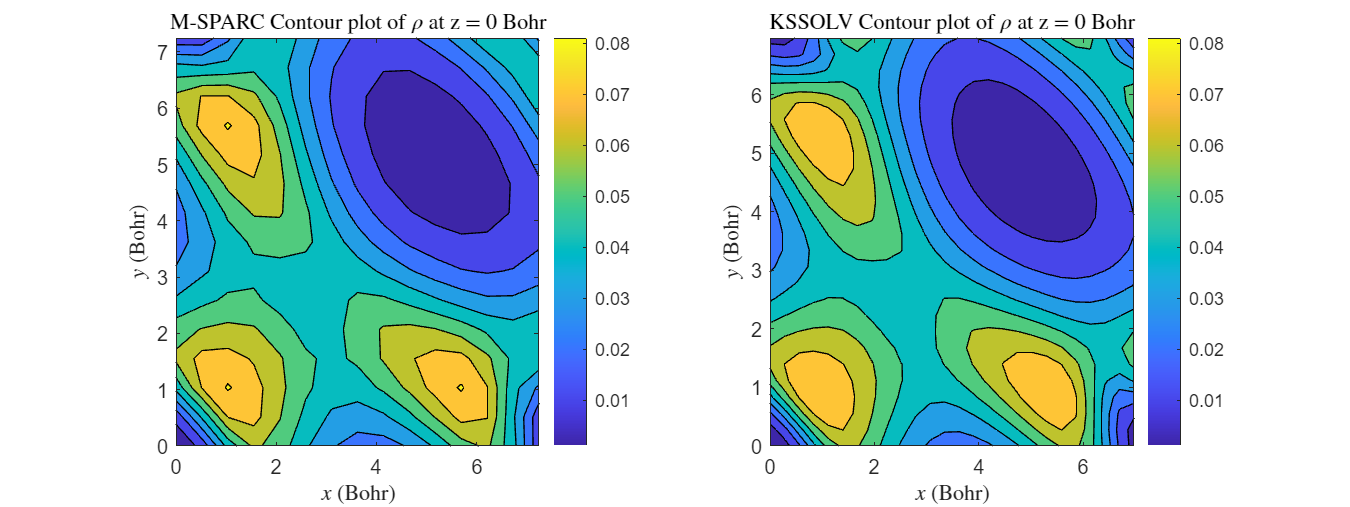

% M-SPARC 
slice_allowed_m = string(linspace(0,S4.L1-S4.dx,S4.Nx));
zslicem = floor(double(slice_allowed_m(1))/S4.dz)+1; % in Bohr 
x = linspace(0,S4.L1,S4.Nx);
y = linspace(0,S4.L2,S4.Ny);
z = linspace(0,S4.L3,S4.Nz);
[X,Y,~] = ndgrid(x,y,z);
rhom = reshape(S4.rho(:,1),[S4.Nx S4.Ny S4.Nz]);
Xm = squeeze(X(:,:,zslicem));
Ym = squeeze(Y(:,:,zslicem));
rhom = squeeze(rhom(:,:,zslicem));

% KSSOLV
L = vecnorm(K_cry4.supercell');
h = L./[K_cry4.n1;K_cry4.n2;K_cry4.n3];
slice_allowed_k = string(linspace(0,L(3)-h(3),K_cry4.n3));
zslicek = floor(double(slice_allowed_k(1))/h(3))+1; % in Bohr 
x = linspace(0,L(1)-h(1),K_cry4.n1);
y = linspace(0,L(2)-h(2),K_cry4.n2);
z = linspace(0,L(3)-h(3),K_cry4.n3);
[X,Y,~] = ndgrid(x,y,z);
Xk = squeeze(X(:,:,zslicek));
Yk = squeeze(Y(:,:,zslicek));
rhok = K_Ham4.rho;
rhok = squeeze(rhok(:,:,zslicek));

fig2 = figure();
fig2.Position(3:4) = [1200, 450];
bottom = min(min(rhom(:)),min(rhok(:)));
top  = max(max(rhom(:)),max(rhok(:)));
subplot(1,2,1)
contourf(Xm,Ym,rhom)
shading interp;
colorbar
title("M-SPARC Contour plot of $\rho$ at z = "+ num2str((zslicem-1)*S4.dy,2) + " Bohr", 'Interpreter','latex')
xlabel("$x$ (Bohr)",'Interpreter','latex')
ylabel("$y$ (Bohr)",'Interpreter','latex')
clim manual
clim([bottom top]);

subplot(1,2,2)
contourf(Xk,Yk,rhok)
shading interp;
title("KSSOLV Contour plot of $\rho$ at z = "+ num2str((zslicek-1)*h(3),2) + " Bohr", 'Interpreter','latex')
xlabel("$x$ (Bohr)",'Interpreter','latex')
ylabel("$y$ (Bohr)",'Interpreter','latex')
clim manual
clim([bottom top]);
colorbar;

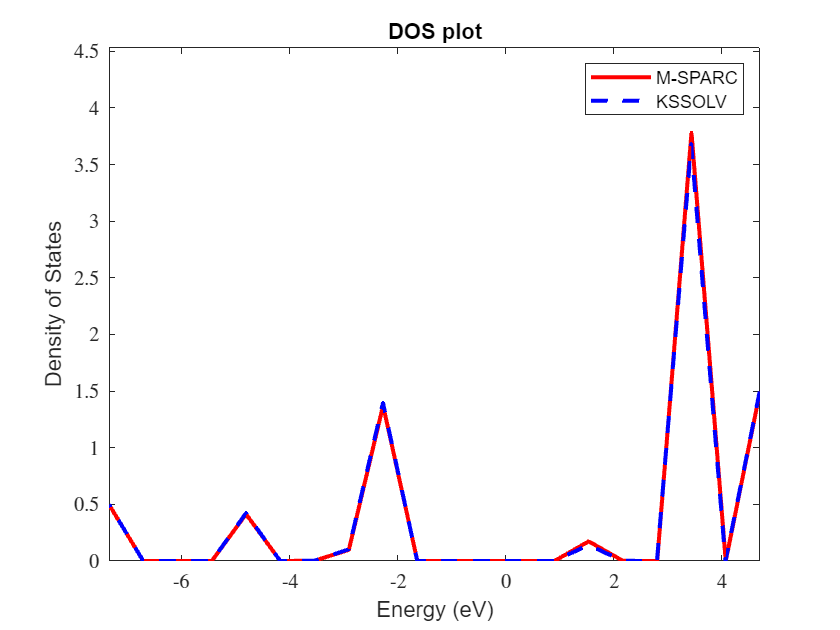

len = min(S4.Nev,max(K_wf4.ncols));
[Em_eV, DOSm_eV] = eig2DOS(S4.EigVal(1:len,:),S4.wkpt);
[Ek_eV, DOSk_eV] = eig2DOS(reshape(K_info4.Eigvals,[],K_Ham4.nkpts),K_Ham4.wks);
Ek_eV = Ek_eV - (min(Ek_eV)-min(Em_eV));
figure; 
hold on; box on; hold on;
plot(Em_eV, DOSm_eV, 'r','linewidth',2,'LineStyle','-');
plot(Ek_eV, DOSk_eV, 'b','linewidth',2,'LineStyle','--');
xlim([min(Em_eV), max(Em_eV)]);
ylim([0, max(DOSm_eV(:))*1.2]);
xlabel('Energy (eV)');
ylabel('Density of States');
set(gca,'TickLabelInterpreter', 'latex');
legend("M-SPARC", "KSSOLV")
title("DOS plot")

## 2D Surfaces

We use a water surface as an example. For simulating 2D surfaces, we need to define the **Bravais lattice **as crystal. Here, we need to add a large vacuum in the Dirichlet direction to avoid the effects from periodic images. We define the Dirichlet directions below.

Lat_scale5 = [5.67 5.67 18.90];
Latvec5 = [1 0 0; 0 1 0; 0 0 1];
dir5 = 3;

Next, we define the atom symbols, number of atoms and their reduced coordinates. 

atom_list5 = ["H","O"];
natom_list5 = [2,1];
coord5 = [ 0.7522 0.4999 0.6643; 0.2476 0.4999 0.6643; 0.4999 0.4999 0.6057];

Again, we define the number of k-points along preiodic directions. 

nk5 = 2; % along each direction

Then we start the calculation in M-SPARC and select the mesh spacing $h$ again. 

h5 = 0.5; % in Bohr

addpath(MSPARC_root);
addpath(fullfile(MSPARC_root,"src"));
addpath("M-SPARC\");
% Real space toolbox M-SPARC
msparc_surface(Lat_scale5,Latvec5,atom_list5,natom_list5,coord5,dir5,h5,nk5,MSPARC_root);
S5 = msparc("M-SPARC/surface");

 Reading .inpt file ...


<INPT>
# $ cat M-SPARC/surface.inpt
LATVEC_SCALE: 5.670000 5.670000 18.900000
LATVEC: 1.000000 0.000000 0.000000
 0.000000 1.000000 0.000000
 0.000000 0.000000 1.000000
MESH_SPACING: 0.500000
KPOINT_GRID: 2 2 1
KPOINT_SHIFT: 0 0 0
BC: P P D 
EXCHANGE_CORRELATION: GGA_PBE
SMEARING: 1E-8
<\INPT>

 Reading .ion file ...
 Number of atom types : 2
 Total number of atoms: 3
 Default atomic mass for H is 1.007975
 Default atomic mass for O is 15.999400
 pseudo_dir # 1 = 01_H_1_1.0_1.0_pbe_v1.0.psp8
 pseudo_dir # 2 = 08_O_6_1.2_1.4_pbe_n_v1.0.psp8

 COORD:
   4.264974000000000   2.834433000000000  12.555269999999998
   1.403892000000000   2.834433000000000  12.555269999999998
   2.834433000000000   2.834433000000000  11.447730000000000

atom type 1, l = 0, r_core read 1.03328, change to rmax where |UdV| < 1E-8, 1.05000.
atom type 1, l = 1, r_core read 1.00283, change to rmax where |UdV| < 1E-8, 1.02000.
atom type 2, l = 0, r_core read 1.35246, change to rmax where |Ud

rmpath(MSPARC_root);
rmpath(fullfile(MSPARC_root,"src"));
rmpath("M-SPARC\");

Next, we run it in KSSOLV and define the cufoff energy. 

Ecut5 = 15; % in Ha

% path and check
addpath(KSSOLV_root);
addpath("KSSOLV\");
KSSOLV_startup;
[K_cry5,K_Ham5,K_w56,K_info5] = kssolv_surface(Lat_scale5,Latvec5,atom_list5,natom_list5,coord5,dir5,Ecut5,nk5);

The pseudopotential for H is loaded from C:\Users\tvekua\OneDrive - MathWorks\Desktop\DFTMaterial\KSSOLV\/ppdata/default/H_ONCV_PBE-1.0.upf
The pseudopotential for O is loaded from C:\Users\tvekua\OneDrive - MathWorks\Desktop\DFTMaterial\KSSOLV\/ppdata/default/O_ONCV_PBE-1.0.upf
Regular SCF for Pure DFT
Beging SCF4C calculation for surface...
SCF iter   1:
eigtol =   1.000e-02
Rel Vtot Err    =            1.796e-01
Total Energy    = -1.6704243320250e+01
SCF iter   2:
eigtol =   1.000e-02
Rel Vtot Err    =            1.056e-01
Total Energy    = -1.6701448418547e+01
SCF iter   3:
eigtol =   1.000e-02
Rel Vtot Err    =            5.288e-02
Total Energy    = -1.6714283368620e+01
SCF iter   4:
eigtol =   6.610e-03
Rel Vtot Err    =            6.045e-03
Total Energy    = -1.6718064290339e+01
SCF iter   5:
eigtol =   7.556e-04
Rel Vtot Err    =            1.274e-03
Total Energy    = -1.6718128148942e+01
SCF iter   6:
eigtol =   1.593e-04
Rel Vtot Err    =            2.235e-04
Total Energy    

rmpath(KSSOLV_root);
rmpath("KSSOLV\");

fprintf("Total energy of the surface from M-SPARC is %.6f Ha\n", S5.Etotal);

Total energy of the surface from M-SPARC is -17.806628 Ha


fprintf("Total energy of the surface from KSSOLV is %.6f Ha\n", K_info5.Etotvec(end));

Total energy of the surface from KSSOLV is -16.718128 Ha


We visualize the electron density below. Since the pseudopotential are not identical and the number of valence electrons is different, the electron density are not the same at all.

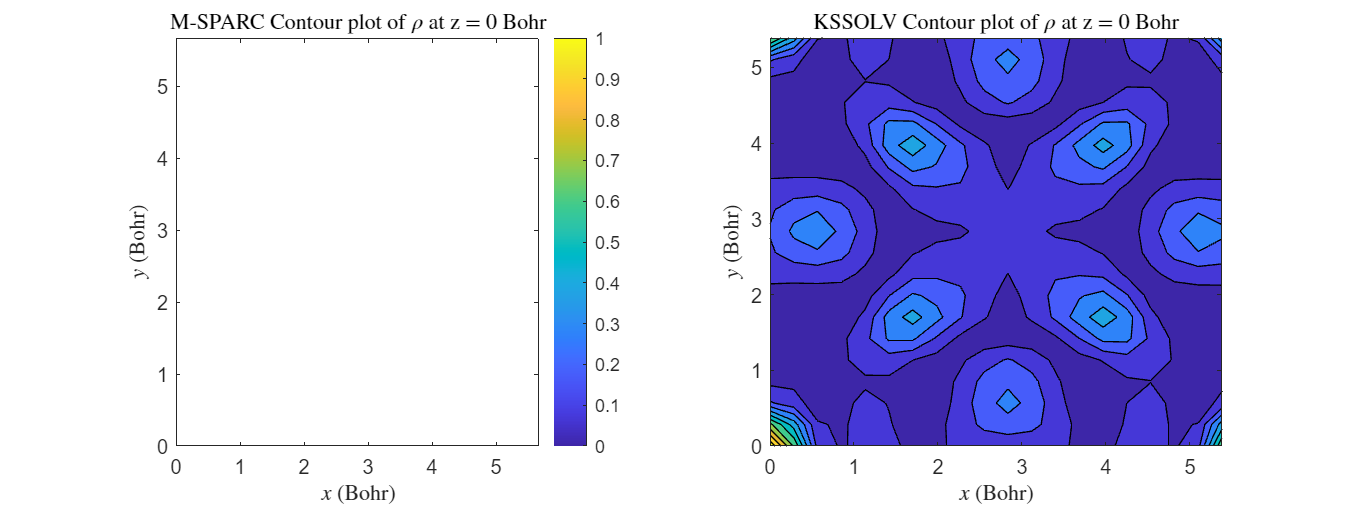

% M-SPARC 
slice_allowed_m = string(linspace(0,S5.L3-S5.dz,S5.Nz));
zslicem = floor(double(slice_allowed_m(1))/S5.dz)+1; % in Bohr 
x = linspace(0,S5.L1,S5.Nx);
y = linspace(0,S5.L2,S5.Ny);
z = linspace(0,S5.L3,S5.Nz);
[X,Y,~] = ndgrid(x,y,z);
rhom = reshape(S5.rho(:,1),[S5.Nx S5.Ny S5.Nz]);
Xm = squeeze(X(:,:,zslicem));
Ym = squeeze(Y(:,:,zslicem));
rhom = squeeze(rhom(:,:,zslicem));

% KSSOLV
L = vecnorm(K_cry5.supercell');
h = L'./[K_cry5.n1;K_cry5.n2;K_cry5.n3];
slice_allowed_k = string(linspace(0,L(3)-h(3),K_cry5.n3));
zslicek = floor(double(slice_allowed_k(1))/h(3))+1; % in Bohr 
x = linspace(0,L(1)-h(1),K_cry5.n1);
y = linspace(0,L(2)-h(2),K_cry5.n2);
z = linspace(0,L(3)-h(3),K_cry5.n3);
[X,Y,~] = ndgrid(x,y,z);
Xk = squeeze(X(:,:,zslicek));
Yk = squeeze(Y(:,:,zslicek));
rhok = K_Ham5.rho;
rhok = squeeze(rhok(:,:,zslicek));

fig2 = figure();
fig2.Position(3:4) = [1200, 450];
subplot(1,2,1)
shading interp;
colorbar
contourf(Xm,Ym,rhom)
shading interp;
colorbar
title("M-SPARC Contour plot of $\rho$ at z = "+ num2str((zslicem-1)*S5.dz,2) + " Bohr", 'Interpreter','latex')
xlabel("$x$ (Bohr)",'Interpreter','latex')
ylabel("$y$ (Bohr)",'Interpreter','latex')

subplot(1,2,2)
contourf(Xk,Yk,rhok)
title("KSSOLV Contour plot of $\rho$ at z = "+ num2str((zslicek-1)*h(3),2) + " Bohr", 'Interpreter','latex')
xlabel("$x$ (Bohr)",'Interpreter','latex')
ylabel("$y$ (Bohr)",'Interpreter','latex')

## 1D Wires

We use water wire (H2O) as an example. For 1D wire system, we need to define the **Bravais lattice **as crystal. Here, we need to add a large vacuum in the Dirichlet direction to avoid the effects from periodic images. And we define the periodic directions below.

Lat_scale6 =  [14 14 6];
Latvec6 = [1 0 0; 0 1 0; 0 0 1];
dir6 = 3;

Next, we define the atom symbols, numbe of atoms and their reduced coordinates. 

atom_list6 = ["H","O"];
natom_list6 = [2,1];
coord6 = [0.52 0.5 0.74; 0.52 0.5 0.26; 0.45 0.5 0.5];

Again, we define the number of k-points along preiodic directions. 

nk6 = 2; % along each direction

Then we start the calculation in M-SPARC and select the mesh spacing $h$ again. 

h6 = 0.4; % in Bohr

addpath(MSPARC_root);
addpath(fullfile(MSPARC_root,"src"));
addpath("M-SPARC\");
% Real space toolbox M-SPARC
msparc_wire(Lat_scale6,Latvec6,atom_list6,natom_list6,coord6,dir6,h6,nk6,MSPARC_root);
S6 = msparc("M-SPARC/wire");

 Reading .inpt file ...


<INPT>
# $ cat M-SPARC/wire.inpt
LATVEC_SCALE: 14.000000 14.000000 6.000000
LATVEC: 1.000000 0.000000 0.000000
 0.000000 1.000000 0.000000
 0.000000 0.000000 1.000000
MESH_SPACING: 0.400000
KPOINT_GRID: 1 1 2
KPOINT_SHIFT: 0 0 0
BC: D D P 
EXCHANGE_CORRELATION: GGA_PBE
<\INPT>

 Reading .ion file ...
 Number of atom types : 2
 Total number of atoms: 3
 Default atomic mass for H is 1.007975
 Default atomic mass for O is 15.999400
 pseudo_dir # 1 = 01_H_1_1.0_1.0_pbe_v1.0.psp8
 pseudo_dir # 2 = 08_O_6_1.2_1.4_pbe_n_v1.0.psp8

 COORD:
   7.280000000000000   7.000000000000000   4.440000000000000
   7.280000000000000   7.000000000000000   1.560000000000000
   6.300000000000000   7.000000000000000   3.000000000000000

atom type 1, l = 0, r_core read 1.03328, change to rmax where |UdV| < 1E-8, 1.05000.
atom type 1, l = 1, r_core read 1.00283, change to rmax where |UdV| < 1E-8, 1.02000.
atom type 2, l = 0, r_core read 1.35246, change to rmax where |UdV| < 1E-8, 1.3700

rmpath(MSPARC_root);
rmpath(fullfile(MSPARC_root,"src"));
rmpath("M-SPARC\");

Next, we run it in KSSOLV and define the cufoff energy. 

Ecut6 = 15; % in Ha

% path and check
addpath(KSSOLV_root);
addpath("KSSOLV\");
KSSOLV_startup;
[K_cry6,K_Ham6,K_wf6,K_info6] = kssolv_surface(Lat_scale6,Latvec6,atom_list6,natom_list6,coord6,dir6,Ecut6,nk6);

The pseudopotential for H is loaded from C:\Users\tvekua\OneDrive - MathWorks\Desktop\DFTMaterial\KSSOLV\/ppdata/default/H_ONCV_PBE-1.0.upf
The pseudopotential for O is loaded from C:\Users\tvekua\OneDrive - MathWorks\Desktop\DFTMaterial\KSSOLV\/ppdata/default/O_ONCV_PBE-1.0.upf
Regular SCF for Pure DFT
Beging SCF4C calculation for surface...
SCF iter   1:
eigtol =   1.000e-02
Rel Vtot Err    =            1.612e-01
Total Energy    = -1.6703673105271e+01
SCF iter   2:
eigtol =   1.000e-02
Rel Vtot Err    =            8.348e-02
Total Energy    = -1.6699322777553e+01
SCF iter   3:
eigtol =   1.000e-02
Rel Vtot Err    =            5.223e-02
Total Energy    = -1.6712194316704e+01
SCF iter   4:
eigtol =   6.529e-03
Rel Vtot Err    =            8.080e-03
Total Energy    = -1.6720021504056e+01
SCF iter   5:
eigtol =   1.010e-03
Rel Vtot Err    =            4.941e-03
Total Energy    = -1.6720039105092e+01
SCF iter   6:
eigtol =   6.176e-04
Rel Vtot Err    =            8.835e-04
Total Energy    

rmpath(KSSOLV_root);
rmpath("KSSOLV\");

fprintf("Total energy of the wire from M-SPARC is %.6f Ha\n", S6.Etotal);

Total energy of the wire from M-SPARC is -17.687909 Ha


fprintf("Total energy of the wire from KSSOLV is %.6f Ha\n", K_info6.Etotvec(end));

Total energy of the wire from KSSOLV is -16.720046 Ha


We visualize the electron density below. Since the pseudopotentials are not identical and the number of valence electrons is different, the visualized electron densities from the two toolboxes are quite different from each other.

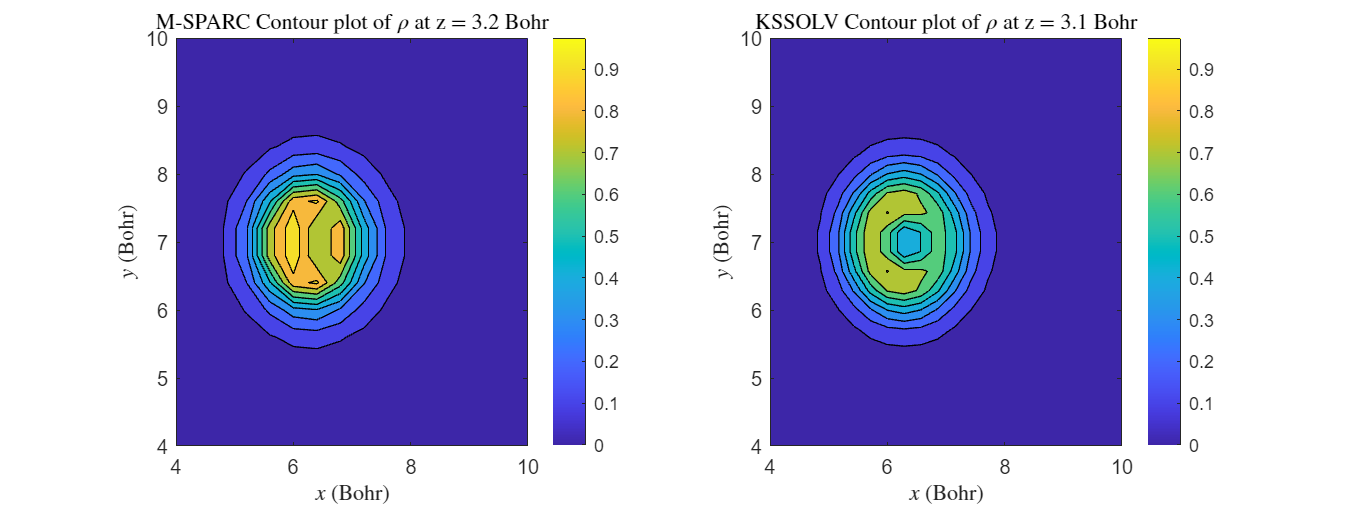

% M-SPARC 
slice_allowed_m = string(linspace(0,S6.L3-S6.dz,S6.Nz));
zslicem = floor(double(slice_allowed_m(9))/S6.dz)+1; % in Bohr 
x = linspace(0,S6.L1,S6.Nx);
y = linspace(0,S6.L2,S6.Ny);
z = linspace(0,S6.L3,S6.Nz);
[X,Y,~] = ndgrid(x,y,z);
rhom = reshape(S6.rho(:,1),[S6.Nx S6.Ny S6.Nz]);
Xm = squeeze(X(:,:,zslicem));
Ym = squeeze(Y(:,:,zslicem));
rhom = squeeze(rhom(:,:,zslicem));

% KSSOLV
L = vecnorm(K_cry6.supercell');
h = L'./[K_cry6.n1;K_cry6.n2;K_cry6.n3];
slice_allowed_k = string(linspace(0,L(3)-h(3),K_cry6.n3));
zslicek = floor(double(slice_allowed_k(12))/h(3))+1; % in Bohr 
x = linspace(0,L(1)-h(1),K_cry6.n1);
y = linspace(0,L(2)-h(2),K_cry6.n2);
z = linspace(0,L(3)-h(3),K_cry6.n3);
[X,Y,Z] = ndgrid(x,y,z);
Xk = squeeze(X(:,:,zslicek));
Yk = squeeze(Y(:,:,zslicek));
rhok = K_Ham6.rho;
rhok = squeeze(rhok(:,:,zslicek));

bottom = min(min(rhom(:)),min(rhok(:)));
top  = max(max(rhom(:)),max(rhok(:)));
fig2 = figure();
fig2.Position(3:4) = [1200, 450];
subplot(1,2,1)
contourf(Xm,Ym,rhom)
shading interp;
colorbar
title("M-SPARC Contour plot of $\rho$ at z = "+ num2str((zslicem-1)*S6.dy,2) + " Bohr", 'Interpreter','latex')
xlabel("$x$ (Bohr)",'Interpreter','latex')
ylabel("$y$ (Bohr)",'Interpreter','latex')
xlim([4 10])
ylim([4 10])
clim manual
clim([bottom top]);

subplot(1,2,2)
contourf(Xk,Yk,rhok)
shading interp;
colorbar
title("KSSOLV Contour plot of $\rho$ at z = "+ num2str((zslicek-1)*h(3),2) + " Bohr", 'Interpreter','latex')
xlabel("$x$ (Bohr)",'Interpreter','latex')
ylabel("$y$ (Bohr)",'Interpreter','latex')
xlim([4 10])
ylim([4 10])
clim manual
clim([bottom top]);
colorbar;

## Functions

function [E_eV, DOS_eV] = eig2DOS(lambda1,wkpt)
% plot Density Of States (DOS)
eV2Ha = 1 / 27.21138397;
% Plot DOS in eV
% convert lambda to eV
lambda1_eV = lambda1 / eV2Ha;
nkpts = size(lambda1_eV,2);
assert(length(wkpt) == nkpts);
assert(sum(wkpt) == 1);
mu = 0.1; % in eV
N = 5 * size(lambda1_eV,1);
lambda_max = max(max(lambda1_eV));
lambda_min = min(min(lambda1_eV));

for kpt = 1:nkpts
    [DOS_eV_temp1,E_eV] = eig2DOS_gamma(lambda1_eV(:,kpt), N, mu, lambda_max, lambda_min);
    
    if kpt==1
        DOS_eV = DOS_eV_temp1*wkpt(1);
    else
        DOS_eV = DOS_eV + DOS_eV_temp1*wkpt(kpt);
    end
end
end

function [DOS, E] = eig2DOS_gamma(lambda,N,sigma,lambda_min,lambda_max)
% EIG2DOS plots density of states (DOS) based on the eigenvalues
% DOE(e) = 2 \sum_{n=1}^{Ns} delta(lambda(n) -  e)
%
% @param lambda Eigenvalues
% @param n      Number of points in E
% @param sigma  Standard deviation
%
% @author       Qimen Xu <qimenxu@gatech.edu>

buf = 0;
Emin = lambda_min - buf;
Emax = lambda_max + buf;
E = linspace(Emin, Emax, N);
DOS = sum(gauss_distribution(colminusrow(E, lambda), sigma), 2);
end

function f = gauss_distribution(x, s)
% f(x,mu,s) = 1/(s*sqrt(2*pi)) * exp( -0.5 * ((x)/s)^2 )
p1 = -.5 * ((x)./s) .^ 2;
p2 = (s * sqrt(2*pi));
f = exp(p1) ./ p2; 
end

% tool function colminusrow
function xmy = colminusrow(x,y)
% A column vector x minus a row vector.
% In Matlab versions after R2018b, it's just x - y
[xx,yy] = ndgrid(x,y);
xmy = xx - yy;
end